# EE 146: Computer Vision

# Buddy Ugwumba SID: 862063029

# Lab 6: K-NN Classification, K-mean Classification for Segmentation

# Date: 02/09/2022

Goal: Understand basic pattern recognition techniques used in computer vision. 

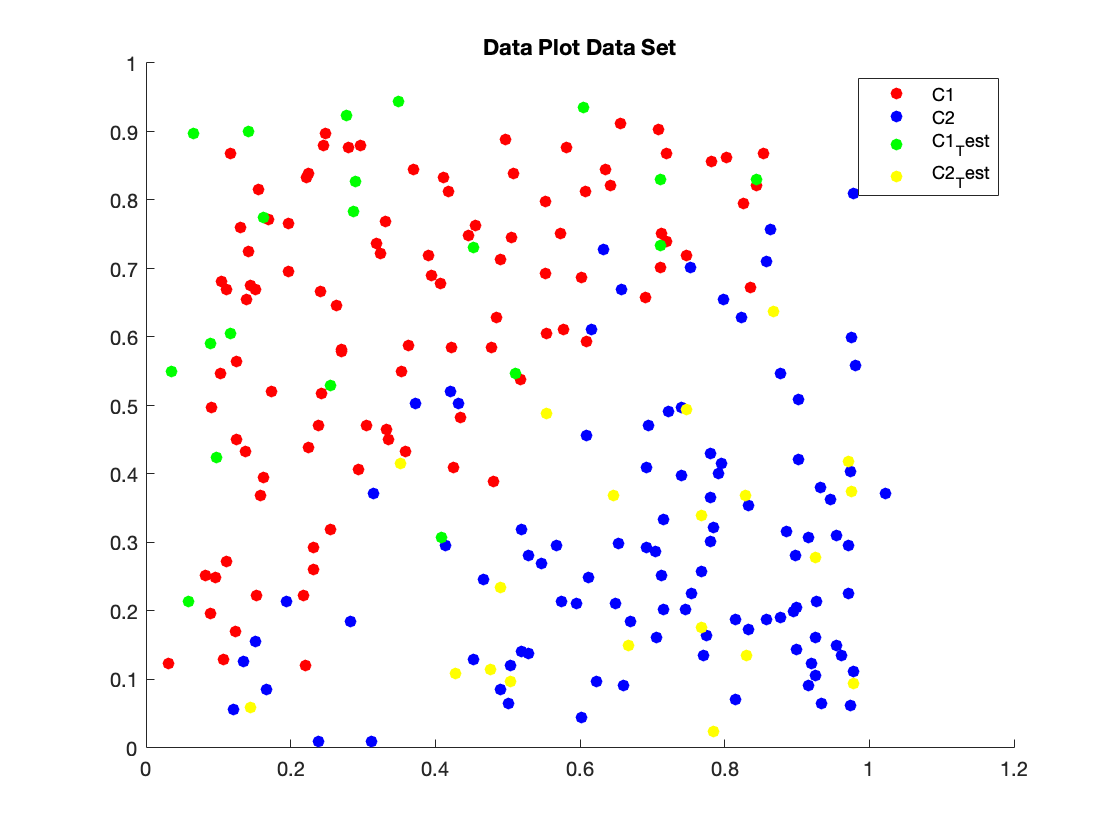

clf
% Problem 1: load('2Class_KNN_Data.mat') will give you 4 variables
load("2Class_KNN_Data.mat")
% Now I must classify the data using the K-NN classification algorithm
% In this two-class problem (using K = 5), classify a 2D feature vector x 
% into the class that has more “closer” samples than the other class. 
% The test data and sample (training) data are saved into the following text files:

% When you use train_c1 = load(‘Lab51Train’) in Matlab, you will get a Nx2 matrix 
% where N is the number of feature vectors.
% Steps
% 2) Plot the training and test data for two classes using different color and styles.
% Create scatter plot for training data

scatter(c1(:,1), c1(:,2), [], 'red', 'filled'), hold on
scatter(c2(:,1), c2(:,2), 'filled', 'blue'), hold on
% Create scatter plot for test data
scatter(c1test(:,1), c1test(:,2), 'green', 'filled'), hold on
scatter(c2test(:,1), c2test(:,2), 'yellow', 'filled'), hold off
title("Data Plot Data Set"), legend('C1', 'C2', 'C1_Test', 'C2_Test')

% Concatenate the vectors
training_data = cat(1, c1, c2);
test_data = cat(1, c1test, c2test);
% Create labels; first make an empty array
C1_training_label = zeros(size(c1,1),1);
C1_test_label = ones(size(c1test,1),1);
C2_training_label = ones(size(c2,1),1);
C2_test_label = zeros(size(c2test,1),1);

% Concatenate the labels
training_data_cat = cat(1, C1_training_label, C2_training_label);
testing_data_cat = cat(1, C1_test_label, C2_test_label);
% 3) Use K-NN algorithm
% model1 = fitcknn(training_data, training_data_cat, 'NumNeighbors', 5, 'Standardize',1)
model2 = fitcknn(test_data, testing_data_cat, 'NumNeighbors', 5, 'Standardize',1)

model2 =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 40
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


traiining_predict = predict(model2, test_data);
sum(traiining_predict==testing_data_cat)

ans = 37

% This means that there are 3 errors. My classification error is the following
3/40*100

ans = 7.5000

% My confusion matrix is:
% The first argument for my confusion matrix is the known group and the
% second argument is the predicted group
C = confusionmat(testing_data_cat, traiining_predict)

C =     19     1
     2    18


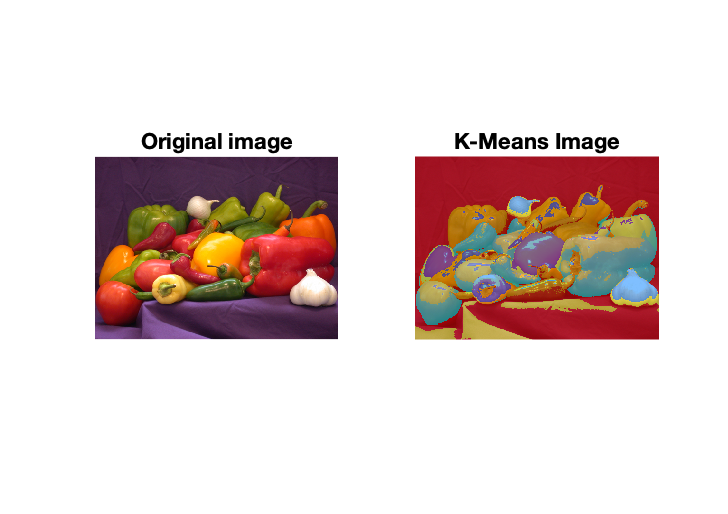

peppers = imread('peppers.png');
subplot(1,2,1), imshow(peppers), title('Original image'), hold on;
% Cluste the feature vector using K-Mean alg
[L,Centers] = imsegkmeans(peppers,7);
% Create the feature vector
B = labeloverlay(peppers,L);
% Display the segmented image
subplot(1,2,2), imshow(B)
title('K-Means Image')